load('v2.mat'); % เก็บรอบที่ 2
rawData = out.simout1

rawData = 1.0e+04 *

    0.0000         0
         0         0
         0         0
    0.0000         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Nround = 21;
Nsample = 201;

% Manipulate matrix
MassData = rawData(:, 2)

MassData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 1)

analogs =     0.0016
         0
         0
    0.0008
         0
         0
         0
         0
         0
         0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =     0.0016         0         0    0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0016         0         0         0         0    0.0008    0.0008         0    0.0016         0         0         0         0         0    0.0016         0         0    0.0008         0         0    0.0040         0         0    0.0016         0         0    0.0008         0         0         0         0
    0.1007    0.0951    0.0919    0.0951    0.0967    0.0991    0.0927    0.0951    0.0975    0.0919    0.0983    0.0967    0.0967    0.0991    0.0903    0.0919    0.0967    0.0919    0.0943    0.0935    0.0975    0.0959    0.0991    0.0967    0.0927    0.0919    0.0959    0.0951    0.0935    0.0959    0.0975    0.0943    0.0959    0.0911    0.0919    0.0951    0.0895    0.0967    0.0919    0.0903    0.0927    0.0943    0.0967    0.0943    0.0975    0.0983    0.0983    0.0951    0.091


% to be used
anaData = cast(anaData, "double");
voltData = anaData %.* 3.3 ./ 4096.0

voltData =     0.0016         0         0    0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0016         0         0         0         0    0.0008    0.0008         0    0.0016         0         0         0         0         0    0.0016         0         0    0.0008         0         0    0.0040         0         0    0.0016         0         0    0.0008         0         0         0         0
    0.1007    0.0951    0.0919    0.0951    0.0967    0.0991    0.0927    0.0951    0.0975    0.0919    0.0983    0.0967    0.0967    0.0991    0.0903    0.0919    0.0967    0.0919    0.0943    0.0935    0.0975    0.0959    0.0991    0.0967    0.0927    0.0919    0.0959    0.0951    0.0935    0.0959    0.0975    0.0943    0.0959    0.0911    0.0919    0.0951    0.0895    0.0967    0.0919    0.0903    0.0927    0.0943    0.0967    0.0943    0.0975    0.0983    0.0983    0.0951    0.09


meanVoltData = mean(voltData, 2)

meanVoltData =     0.0004
    0.0949
    0.2227
    0.3398
    0.4599
    0.5830
    0.7198
    0.8590
    0.9843
    1.1093


stdVolt = std(voltData, 0, 2)

stdVolt =     0.0008
    0.0027
    0.0101
    0.0030
    0.0027
    0.0030
    0.0031
    0.0039
    0.0035
    0.0032



Mass = 0 : 0.5 : 10 % kg

Mass =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000



g = 9.81

g = 9.8100

Force = Mass * g

Force =          0    4.9050    9.8100   14.7150   19.6200   24.5250   29.4300   34.3350   39.2400   44.1450   49.0500   53.9550   58.8600   63.7650   68.6700   73.5750   78.4800   83.3850   88.2900   93.1950   98.1000


gain = 581.395

gain = 581.3950

V_nonAmp = meanVoltData / gain * 1000% mV

V_nonAmp =     0.0007
    0.1632
    0.3830
    0.5845
    0.7910
    1.0027
    1.2381
    1.4775
    1.6930
    1.9081


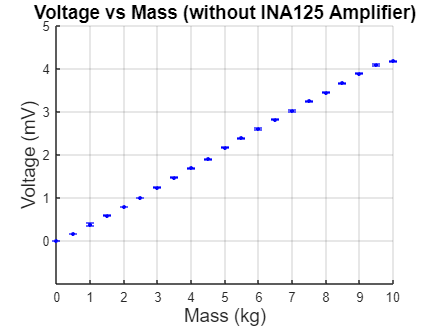

% without INA125

figure;
hold on;
graph_V = errorbar(Mass, V_nonAmp, 2000*stdVolt/gain, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');

% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:1:5);
yticklabels(0:1:5);
grid on;
title('Voltage vs Mass (without INA125 Amplifier)', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 14); 
ylabel('Voltage (mV)', 'FontSize', 14); 
%%legend('Non-Shield South','Location', 'southeast');

hold off;

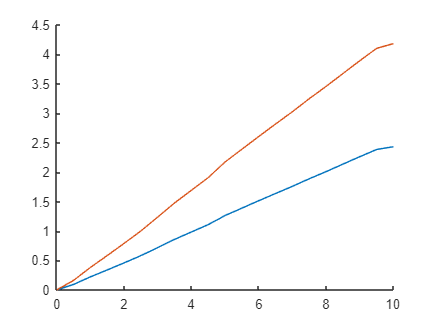

figure;
hold on;
plot(Mass, meanVoltData)
plot(Mass, V_nonAmp)
hold off;

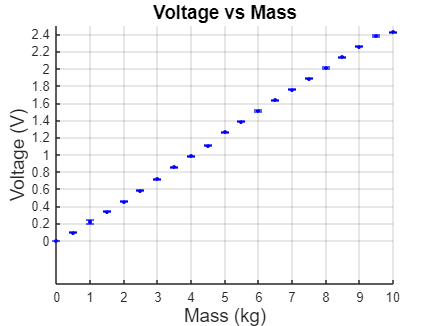


figure;
hold on;
graph_V = errorbar(Mass, meanVoltData, 2*stdVolt, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');

% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 14); 
ylabel('Voltage (V)', 'FontSize', 14); 
%%legend('Non-Shield South','Location', 'southeast');

hold off;

% Fitting
x = Mass;
y = meanVoltData;

% Get coefficients of a line fit through the data.
coefficients = polyfit(x, y, 1)

coefficients =     0.2531   -0.0252


global c1;
global c2;
c1 = coefficients(1)

c1 = 0.2531

c2 = coefficients(2)

c2 = -0.0252

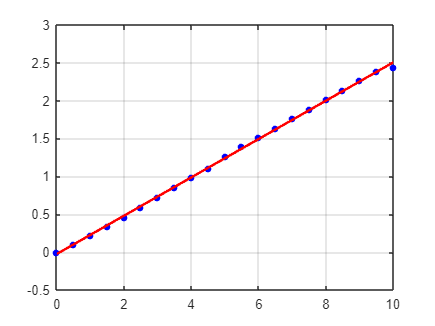


% Create a new x axis with exactly 1000 points (or whatever you want).
xFit = linspace(min(x), max(x), 1000);
% Get the estimated yFit value for each of those 1000 new x locations.
yFit = polyval(coefficients , xFit);
% Plot everything.
plot(x, y, 'b.', 'MarkerSize', 15); % Plot training data.
hold on; % Set hold on so the next plot does not blow away the one we just drew.
plot(xFit, yFit, 'r-', 'LineWidth', 2); % Plot fitted line.
grid on;

% plot and fitting line
figure;
hold on;
graph_V = errorbar(Mass, meanVoltData, 2*stdVolt, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
plot(xFit, yFit, 'r-', 'LineWidth', 0.8); % Plot fitted line.

% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Exerted Force', 'FontSize', 14);
xlabel('Exerted Force (x 9.81 N)', 'FontSize', 14); 
ylabel('Voltage (V)', 'FontSize', 14); 
legend('Voltage', sprintf('y = %.4fx + %.4f', c1, c2), 'Location', 'southeast');
%datatip(graph_V);
coefficients

coefficients =     0.2531   -0.0252


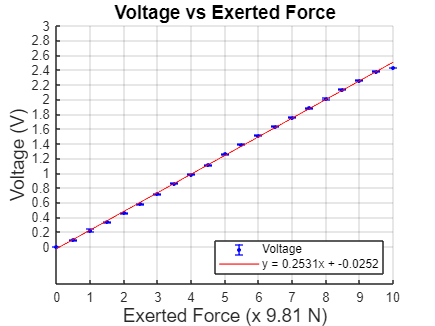

hold off;

% line equation

function v = mass2volt(kg)
    global c1;
    global c2;
    v = c1 * kg + c2;
end

function kg = volt2mass(v)
    global c1;
    global c2;
    kg = (v - c2) / c1;
end

mass2volt(0.5)

ans = 0.1013

mass2volt(1)

ans = 0.2279

volt2mass(0.2279)

ans = 1.0000

volt2mass(2.40)

ans = 9.5819

% predicted mass vs actual mass
Predicted_Mass = volt2mass(meanVoltData)

Predicted_Mass =     0.1011
    0.4746
    0.9793
    1.4423
    1.9167
    2.4029
    2.9436
    3.4936
    3.9886
    4.4825


Actual_Mass = Mass'

Actual_Mass =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


Err_Mass = Predicted_Mass - Actual_Mass

Err_Mass =     0.1011
   -0.0254
   -0.0207
   -0.0577
   -0.0833
   -0.0971
   -0.0564
   -0.0064
   -0.0114
   -0.0175


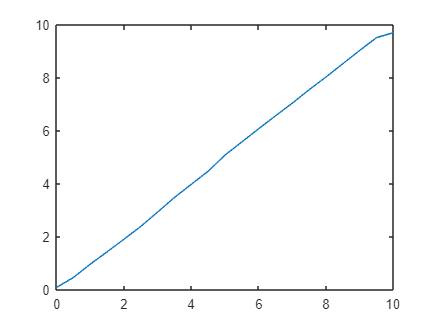


plot(Actual_Mass, Predicted_Mass)


figure;
hold on;
graph_MM = plot(Actual_Mass, Predicted_Mass, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
%plot(xFit, yFit, 'r-', 'LineWidth', 0.8); % Plot fitted line.
plot(linspace(0, 10, 1000), linspace(0, 10, 1000), 'r-', 'LineWidth', 0.8); % ideal line

% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:1:10);
yticklabels(0:1:10);
grid on;
title('Predicted Mass vs Actual Mass', 'FontSize', 14);
xlabel('Actual Mass (kg)', 'FontSize', 14); 
ylabel('Predicted Mass (kg)', 'FontSize', 14); 
legend('Predicted Mass', 'Ideal Prediction (y = x)', 'Location', 'southeast');
%datatip(graph_V);
coefficients

coefficients =     0.2531   -0.0252


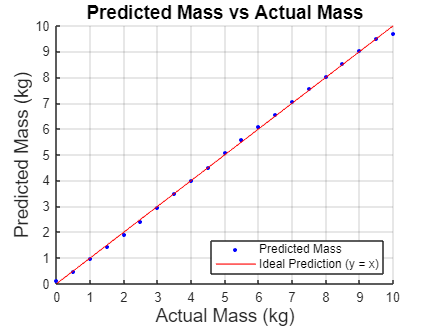

hold off;


table(Actual_Mass, meanVoltData, Predicted_Mass, Err_Mass)

ans = 21×4 table
    Actual_Mass    meanVoltData    Predicted_Mass     Err_Mass 
    ___________    ____________    ______________    __________

          0         0.0003889         0.10111           0.10111
        0.5          0.094911         0.47457          -0.02543
          1           0.22267         0.97933         -0.020673
        1.5           0.33985          1.4423         -0.057687
          2           0.45991          1.9167         -0.083344
        2.5           0.58299          2.4029         -0.097057
          3           0.71983          2.9436          -0.05639
        3.5           0.85902          3.4936        -0.0064398
          4           0.98432          3.9886         -0.011393
        4.5            1.1093          4.4825         -0.017471
          5            1.2635          5.0916          0.091627
        5.5   